% Load dataset
load dataset2.mat

% Symbolically Obtaining Jacobians
sympref('AbbreviateOutput',false);
% Motion Model Variables
x_prev_sym = sym("x_k_minus_1");
y_prev_sym = sym("y_k_minus_1");
theta_prev_sym = sym("theta_k_minus_1");
x_prev_hat_sym = sym("x__hat_k_minus_1");
y_prev_hat_sym = sym("y__hat_k_minus_1");
theta_prev_hat_sym = sym("theta__hat_k_minus_1");
T_sym = sym("T");
v_sym = sym("v_k");
omega_sym = sym("omega_k");
w_v_sym = sym("w_k_v");
w_omega_sym = sym("w_k_omega");

% Observation Model Variables
x_l_sym = sym("x_l", "real");
y_l_sym = sym("y_l", "real");
x_sym = sym("x_k", "real");
y_sym = sym("y_k", "real");
theta_sym = sym("theta_k", "real");
x_check_sym = sym("x__v_k", "real");
y_check_sym = sym("y__v_k", "real");
theta_check_sym = sym("theta__v_k", "real");
d_sym = sym("d", "real");
n_r_sym = sym("n__l_k_r", "real");
n_phi_sym = sym("n__l_k_phi", "real");


% Motion Model
h = [x_prev_sym; y_prev_sym; theta_prev_sym] + ...
    T_sym * [cos(theta_prev_sym) 0; sin(theta_prev_sym) 0; 0 1] ...
    * ([v_sym; omega_sym] + [w_v_sym; w_omega_sym])

$$h = \left(\begin{array}{c} x_{k,-1}+T\,\cos\left(\theta_{k,-1}\right)\,\left(v_{k}+w_{k,v}\right)\\ y_{k,-1}+T\,\sin\left(\theta_{k,-1}\right)\,\left(v_{k}+w_{k,v}\right)\\ \theta_{k,-1}+T\,\left(\omega_{k}+w_{k,\omega }\right) \end{array}\right)$$


H_x_pure = jacobian(h, [x_prev_sym;y_prev_sym;theta_prev_sym])

$$H\_x\_pure = \left(\begin{array}{ccc} 1 & 0 & -T\,\sin\left(\theta_{k,-1}\right)\,\left(v_{k}+w_{k,v}\right)\\ 0 & 1 & T\,\cos\left(\theta_{k,-1}\right)\,\left(v_{k}+w_{k,v}\right)\\ 0 & 0 & 1 \end{array}\right)$$

H_w_pure = jacobian(h, [w_v_sym;w_omega_sym])

$$H\_w\_pure = \left(\begin{array}{cc} T\,\cos\left(\theta_{k,-1}\right) & 0\\ T\,\sin\left(\theta_{k,-1}\right) & 0\\ 0 & T \end{array}\right)$$


old_variables_h = [x_prev_sym;y_prev_sym;theta_prev_sym; ...
    w_v_sym;w_omega_sym];
new_variables_h = [x_prev_hat_sym;y_prev_hat_sym; ...
    theta_prev_hat_sym;0;0];

H_x = subs(H_x_pure, old_variables_h, new_variables_h)

$$H\_x = \left(\begin{array}{ccc} 1 & 0 & -T\,v_{k}\,\sin\left({\hat{\theta }}_{k,-1}\right)\\ 0 & 1 & T\,v_{k}\,\cos\left({\hat{\theta }}_{k,-1}\right)\\ 0 & 0 & 1 \end{array}\right)$$

H_w = subs(H_w_pure, old_variables_h, new_variables_h)

$$H\_w = \left(\begin{array}{cc} T\,\cos\left({\hat{\theta }}_{k,-1}\right) & 0\\ T\,\sin\left({\hat{\theta }}_{k,-1}\right) & 0\\ 0 & T \end{array}\right)$$


% Observation Model
g1 = sqrt((x_l_sym - x_sym - d_sym * cos(theta_sym))^2 + ...
    (y_l_sym - y_sym - d_sym * sin(theta_sym))^2) + n_r_sym;
g2 = atan2(y_l_sym - y_sym - d_sym * sin(theta_sym), ...
    x_l_sym - x_sym - d_sym * cos(theta_sym)) - theta_sym + n_phi_sym;
g = [g1;g2]

$$g = \left(\begin{array}{c} n_{k,r}^{l}+\sqrt{{\left(x_{k}-x_{l}+d\,\cos\left(\theta_{k}\right)\right)}^{2}+{\left(y_{k}-y_{l}+d\,\sin\left(\theta_{k}\right)\right)}^{2}}\\ n_{k,\varphi }^{l}-\theta_{k}+\text{atan2}\left(y_{l}-y_{k}-d\,\sin\left(\theta_{k}\right),x_{l}-x_{k}-d\,\cos\left(\theta_{k}\right)\right) \end{array}\right)$$


G_x_pure = jacobian(g, [x_sym;y_sym;theta_sym])

$$G\_x\_pure = \left(\begin{array}{ccc} \frac{2\,x_{k}-2\,x_{l}+2\,d\,\cos\left(\theta_{k}\right)}{2\,\sqrt{{\left(x_{k}-x_{l}+d\,\cos\left(\theta_{k}\right)\right)}^{2}+{\left(y_{k}-y_{l}+d\,\sin\left(\theta_{k}\right)\right)}^{2}}} & \frac{2\,y_{k}-2\,y_{l}+2\,d\,\sin\left(\theta_{k}\right)}{2\,\sqrt{{\left(x_{k}-x_{l}+d\,\cos\left(\theta_{k}\right)\right)}^{2}+{\left(y_{k}-y_{l}+d\,\sin\left(\theta_{k}\right)\right)}^{2}}} & -\frac{2\,d\,\sin\left(\theta_{k}\right)\,\left(x_{k}-x_{l}+d\,\cos\left(\theta_{k}\right)\right)-2\,d\,\cos\left(\theta_{k}\right)\,\left(y_{k}-y_{l}+d\,\sin\left(\theta_{k}\right)\right)}{2\,\sqrt{{\left(x_{k}-x_{l}+d\,\cos\left(\theta_{k}\right)\right)}^{2}+{\left(y_{k}-y_{l}+d\,\sin\left(\theta_{k}\right)\right)}^{2}}}\\ -\frac{y_{k}-y_{l}+d\,\sin\left(\theta_{k}\right)}{{\left(x_{k}-x_{l}+d\,\cos\left(\theta_{k}\right)\right)}^{2}+{\left(y_{k}-y_{l}+d\,\sin\left(\theta_{k}\right)\right)}^{2}} & \frac{x_{k}-x_{l}+d\,\cos\left(\theta_{k}\right)}{{\left(x_{k}-x_{l}+d\,\cos\left(\theta_{k}\right)\right)}^{2}+{\left(y_{k}-y_{l}+d\,\sin\left(\theta_{k}\right)\right)}^{2}} & \frac{\left(\frac{d\,\cos\left(\theta_{k}\right)}{x_{k}-x_{l}+d\,\cos\left(\theta_{k}\right)}+\frac{d\,\sin\left(\theta_{k}\right)\,\left(y_{k}-y_{l}+d\,\sin\left(\theta_{k}\right)\right)}{{\left(x_{k}-x_{l}+d\,\cos\left(\theta_{k}\right)\right)}^{2}}\right)\,{\left(x_{k}-x_{l}+d\,\cos\left(\theta_{k}\right)\right)}^{2}}{{\left(x_{k}-x_{l}+d\,\cos\left(\theta_{k}\right)\right)}^{2}+{\left(y_{k}-y_{l}+d\,\sin\left(\theta_{k}\right)\right)}^{2}}-1 \end{array}\right)$$

G_n_pure = jacobian(g, [n_r_sym;n_phi_sym])

$$G\_n\_pure = \left(\begin{array}{cc} 1 & 0\\ 0 & 1 \end{array}\right)$$


old_variables_g = [x_sym;y_sym;theta_sym;n_r_sym;n_phi_sym];
new_variables_g = [x_check_sym;y_check_sym;theta_check_sym;0;0];

G_x = subs(G_x_pure, old_variables_g, new_variables_g)

$$G\_x = \left(\begin{array}{ccc} \frac{2\,x_{k}^{v}-2\,x_{l}+2\,d\,\cos\left(\theta_{k}^{v}\right)}{2\,\sqrt{{\left(x_{k}^{v}-x_{l}+d\,\cos\left(\theta_{k}^{v}\right)\right)}^{2}+{\left(y_{k}^{v}-y_{l}+d\,\sin\left(\theta_{k}^{v}\right)\right)}^{2}}} & \frac{2\,y_{k}^{v}-2\,y_{l}+2\,d\,\sin\left(\theta_{k}^{v}\right)}{2\,\sqrt{{\left(x_{k}^{v}-x_{l}+d\,\cos\left(\theta_{k}^{v}\right)\right)}^{2}+{\left(y_{k}^{v}-y_{l}+d\,\sin\left(\theta_{k}^{v}\right)\right)}^{2}}} & -\frac{2\,d\,\sin\left(\theta_{k}^{v}\right)\,\left(x_{k}^{v}-x_{l}+d\,\cos\left(\theta_{k}^{v}\right)\right)-2\,d\,\cos\left(\theta_{k}^{v}\right)\,\left(y_{k}^{v}-y_{l}+d\,\sin\left(\theta_{k}^{v}\right)\right)}{2\,\sqrt{{\left(x_{k}^{v}-x_{l}+d\,\cos\left(\theta_{k}^{v}\right)\right)}^{2}+{\left(y_{k}^{v}-y_{l}+d\,\sin\left(\theta_{k}^{v}\right)\right)}^{2}}}\\ -\frac{y_{k}^{v}-y_{l}+d\,\sin\left(\theta_{k}^{v}\right)}{{\left(x_{k}^{v}-x_{l}+d\,\cos\left(\theta_{k}^{v}\right)\right)}^{2}+{\left(y_{k}^{v}-y_{l}+d\,\sin\left(\theta_{k}^{v}\right)\right)}^{2}} & \frac{x_{k}^{v}-x_{l}+d\,\cos\left(\theta_{k}^{v}\right)}{{\left(x_{k}^{v}-x_{l}+d\,\cos\left(\theta_{k}^{v}\right)\right)}^{2}+{\left(y_{k}^{v}-y_{l}+d\,\sin\left(\theta_{k}^{v}\right)\right)}^{2}} & \frac{\left(\frac{d\,\cos\left(\theta_{k}^{v}\right)}{x_{k}^{v}-x_{l}+d\,\cos\left(\theta_{k}^{v}\right)}+\frac{d\,\sin\left(\theta_{k}^{v}\right)\,\left(y_{k}^{v}-y_{l}+d\,\sin\left(\theta_{k}^{v}\right)\right)}{{\left(x_{k}^{v}-x_{l}+d\,\cos\left(\theta_{k}^{v}\right)\right)}^{2}}\right)\,{\left(x_{k}^{v}-x_{l}+d\,\cos\left(\theta_{k}^{v}\right)\right)}^{2}}{{\left(x_{k}^{v}-x_{l}+d\,\cos\left(\theta_{k}^{v}\right)\right)}^{2}+{\left(y_{k}^{v}-y_{l}+d\,\sin\left(\theta_{k}^{v}\right)\right)}^{2}}-1 \end{array}\right)$$

G_n = subs(G_n_pure, old_variables_g, new_variables_g)

$$G\_n = \left(\begin{array}{cc} 1 & 0\\ 0 & 1 \end{array}\right)$$

% Process data
K = size(t, 1);
T = 1 / 10;
Q_k = diag([v_var, om_var]);
R_k = diag([r_var, b_var]);

% Used for evaluating Jacobians and motion/observation models
% No need for noise jacobian for observation model since it is always
% the identity matrix (the noise is already linear)
h_func = matlabFunction(h);
H_x_func = matlabFunction(H_x_pure);
H_w_func = matlabFunction(H_w_pure);

g_func = matlabFunction(g);
G_x_func = matlabFunction(G_x_pure);

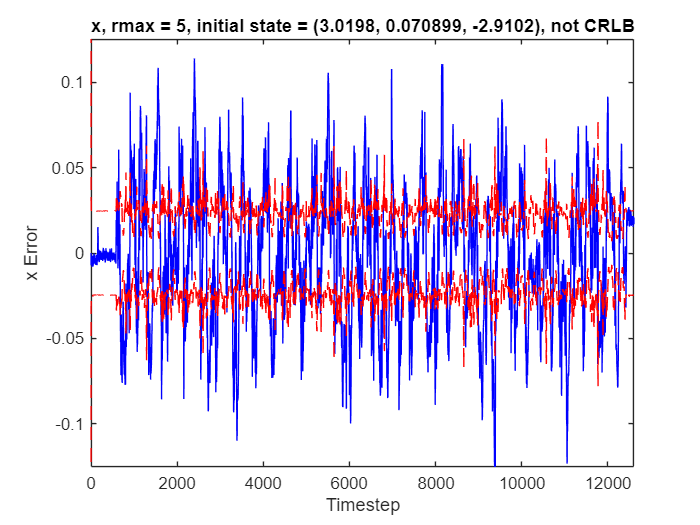

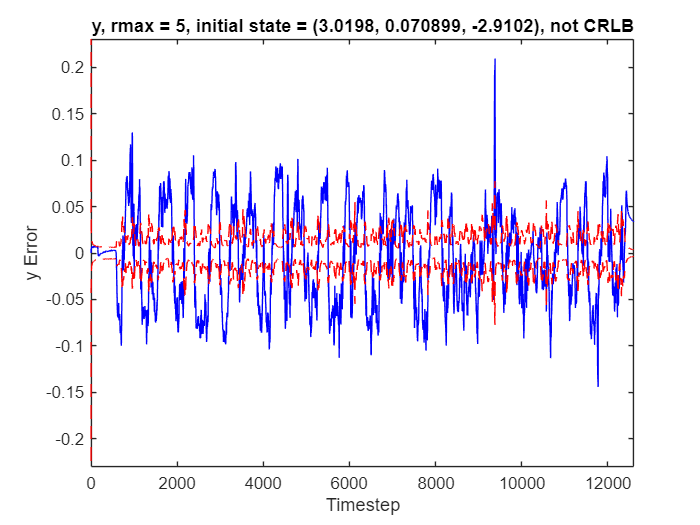

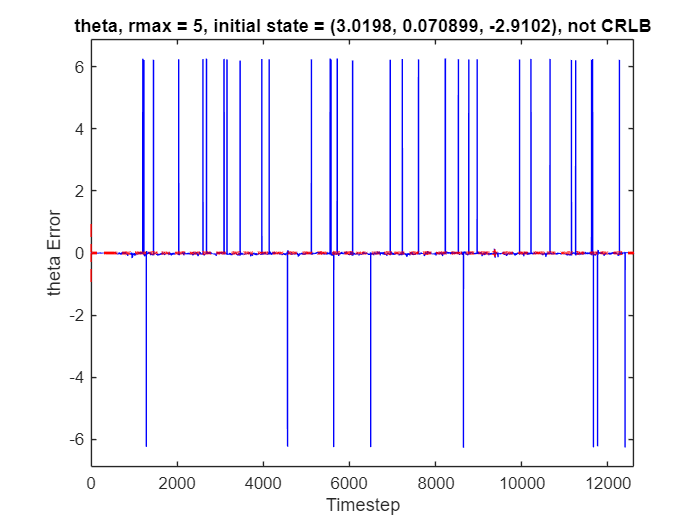

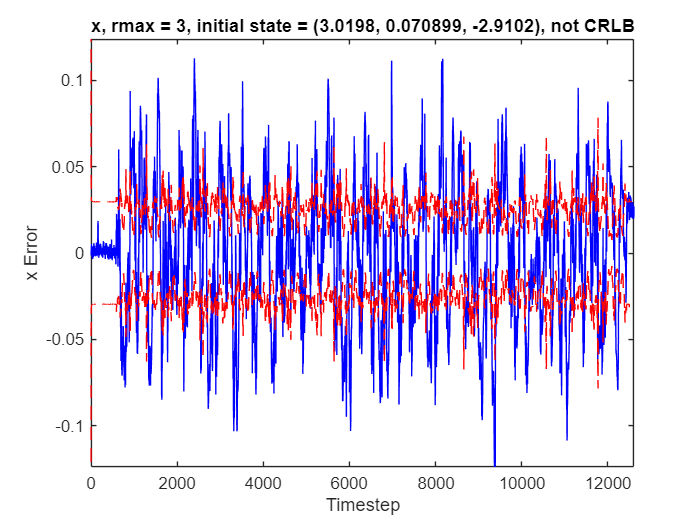

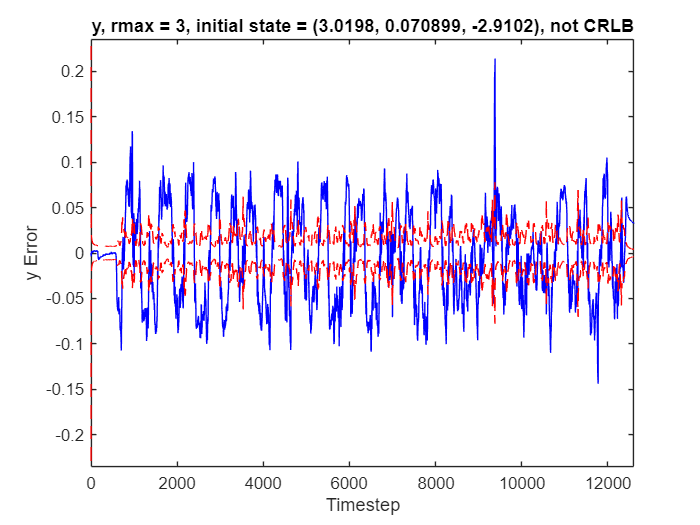

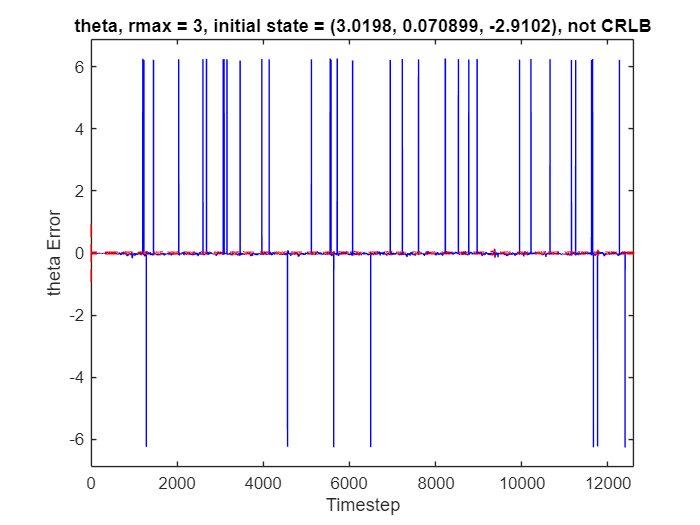

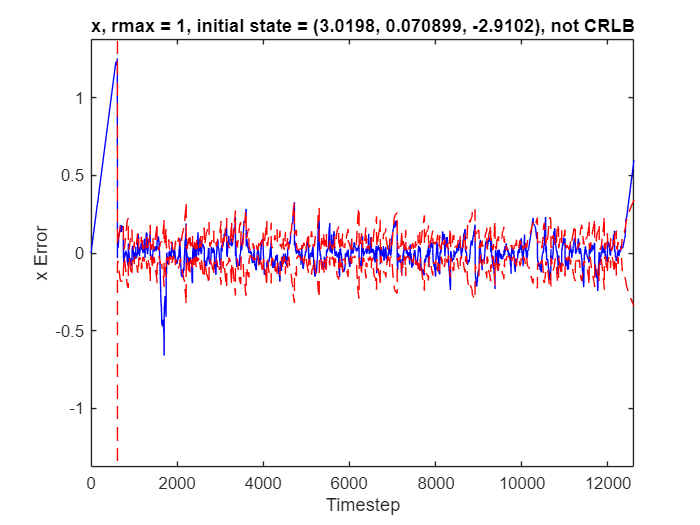

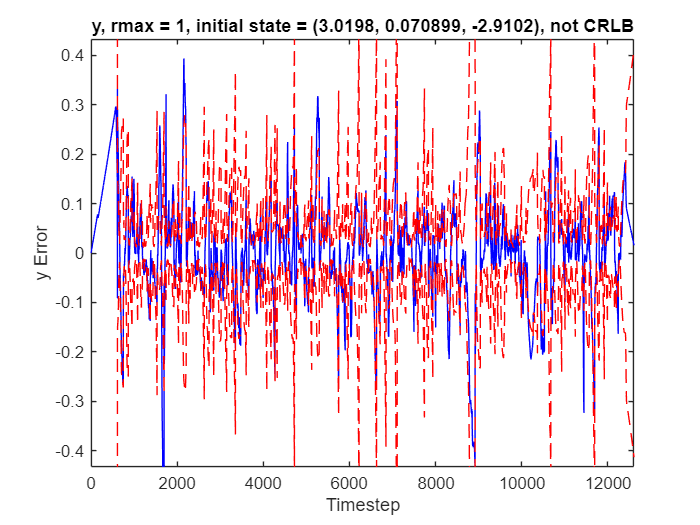

    3.0198
    0.0709
   -2.9102



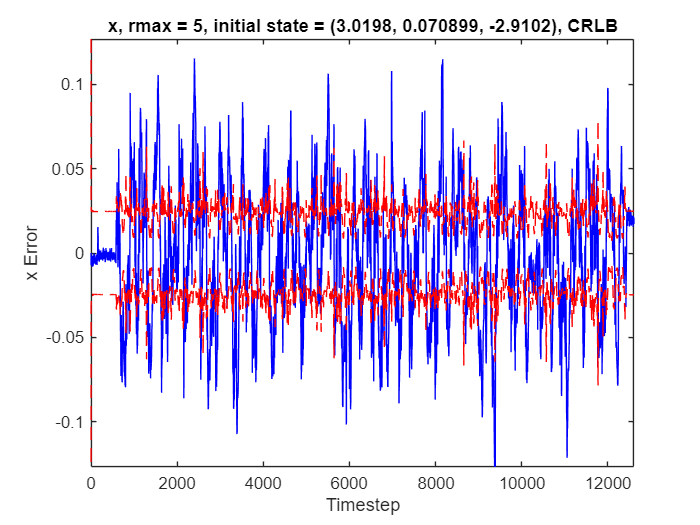

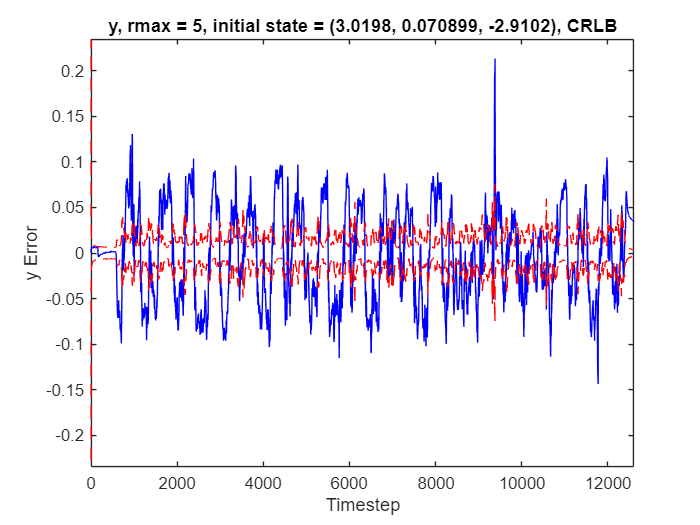

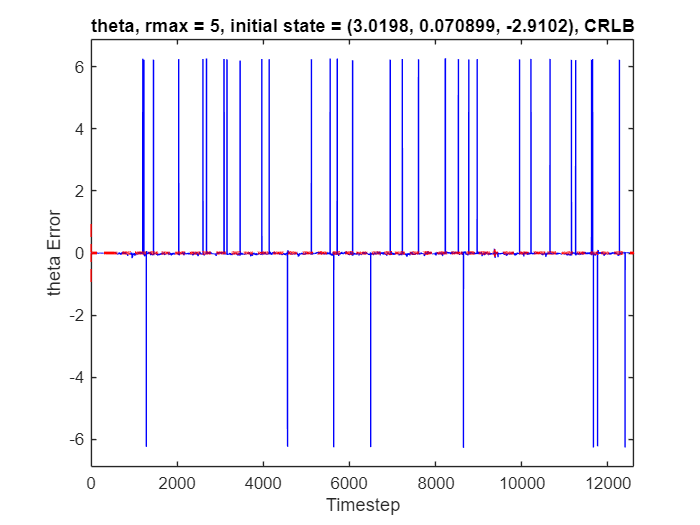

    3.0198
    0.0709
   -2.9102



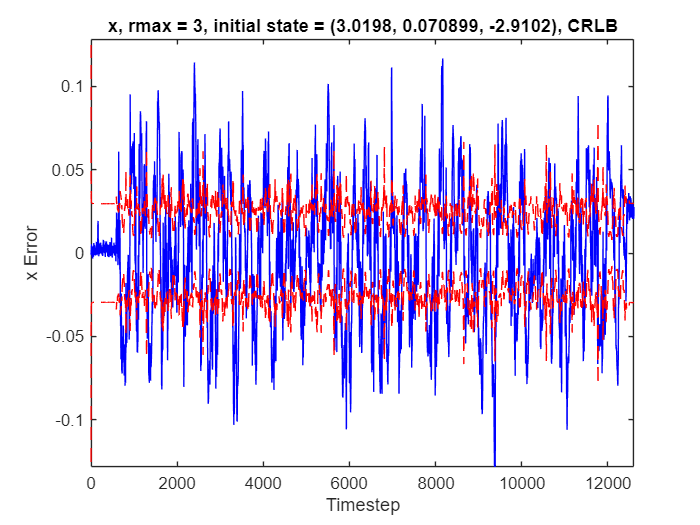

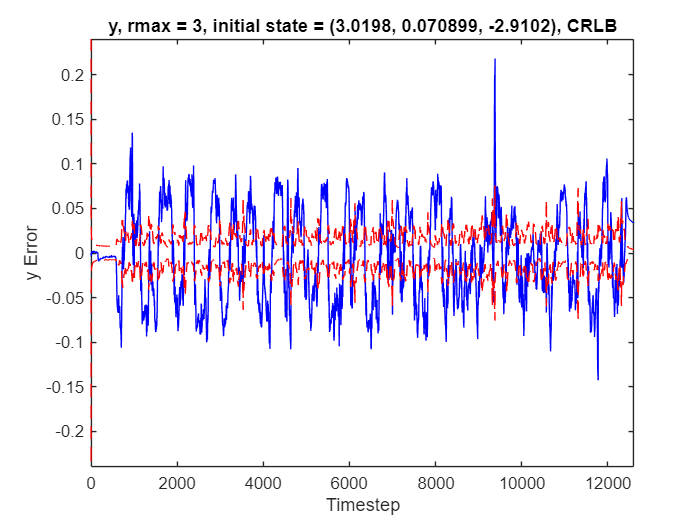

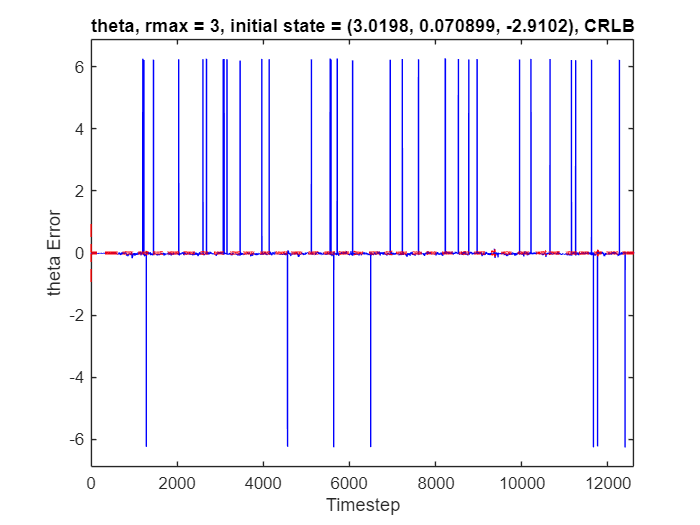

    3.0198
    0.0709
   -2.9102



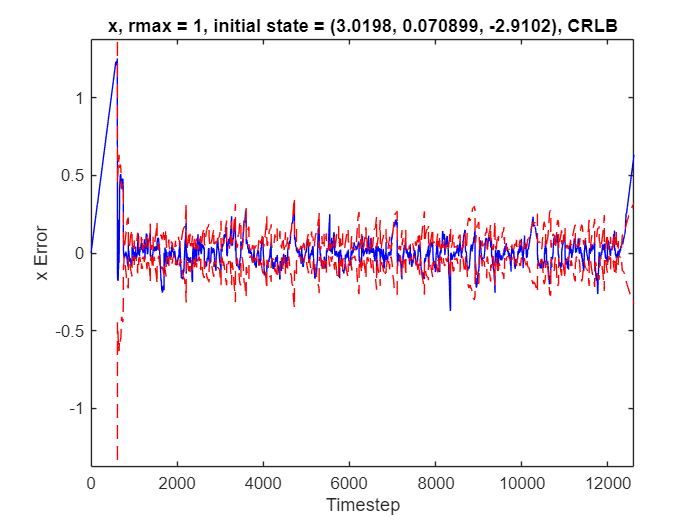

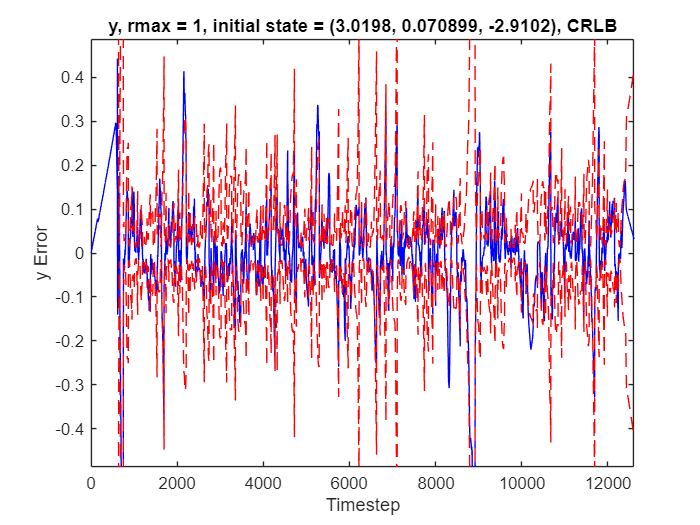

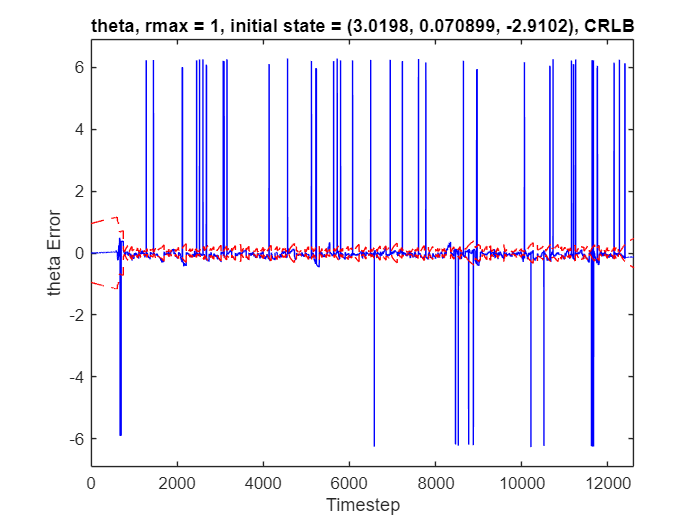

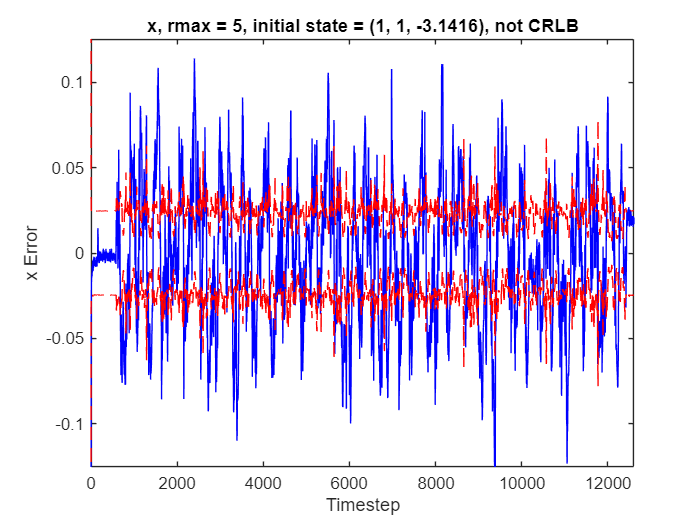

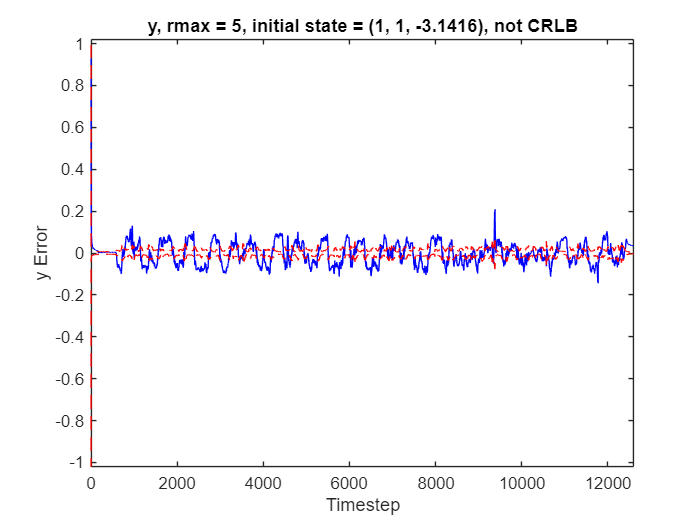

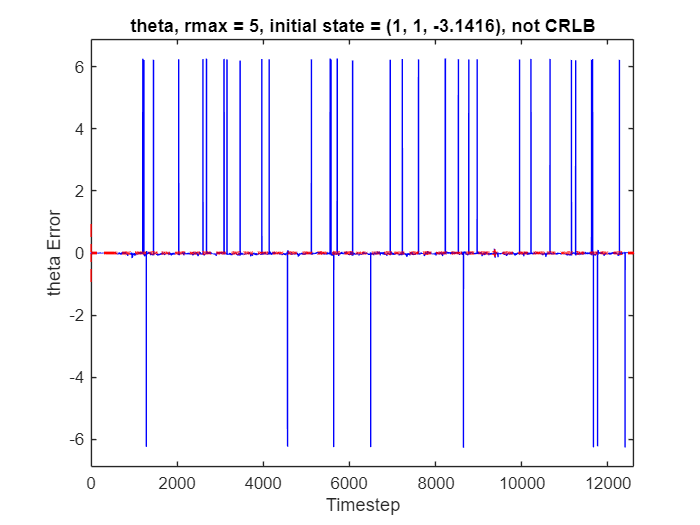

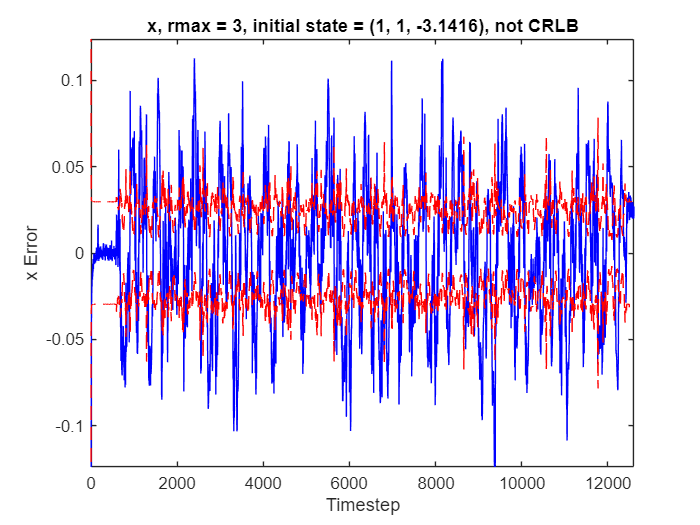

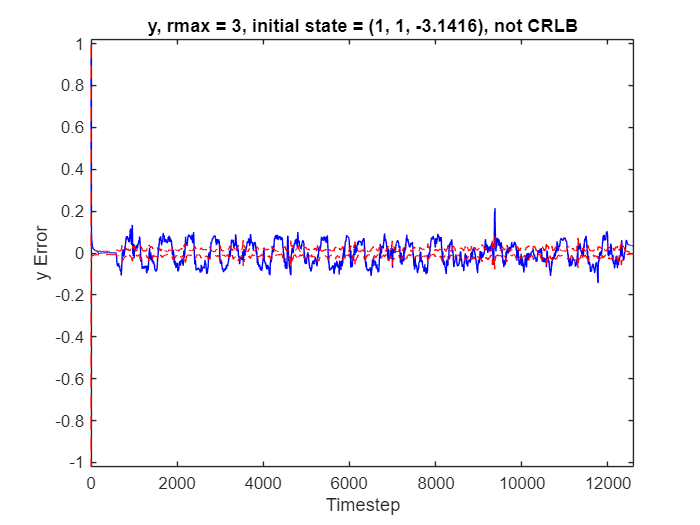

% Running trials and plotting
time = 1:K;
r_max_vals = [5, 3, 1];
initial_states = zeros(3,1,4);
initial_states(:,:,1) = [x_true(1);y_true(1);th_true(1)];
initial_states(:,:,2) = [1;1;0.1];
initial_states(:,:,3) = [x_true(1);y_true(1);th_true(1)];
% EXTREMELY poor initial condition
initial_states(:,:,4) = [1;1;-pi];
initial_covs = zeros(3,3,3);
initial_covs(:,:,1) = diag([1;1;0.1]);
initial_covs(:,:,2) = diag([1;1;0.1]);
initial_covs(:,:,3) = diag([1;1;0.1]);
initial_covs(:,:,4) = diag([1;1;0.1]);

idx = 1;
for i = 1:size(initial_states,3)
    for j = 1:size(r_max_vals,2)
        if i == size(initial_states,3) - 1
            use_CRLB=true;
        else
            use_CRLB=false;
        end
         [x_hat, y_hat, theta_hat, x_var, y_var, theta_var] = EKF( ...
            x_true,y_true,th_true, K, T, d, v, om, l, r, b, Q_k, R_k, h_func, ...
            H_x_func, H_w_func, g_func, G_x_func, r_max_vals(j), ...
            initial_states(:,:,i), initial_covs(:,:,i), use_CRLB);
         x_error = x_hat - x_true;
         y_error = y_hat - y_true;
         theta_error = theta_hat - th_true;

         % Plot x
         figure;
         plot(time, x_error, 'b-');
         hold on;
         plot(time, 3 * sqrt(x_var), 'r--');
         plot(time, -3 * sqrt(x_var), 'r--');
         if use_CRLB
             title( ['x, rmax = ' num2str(r_max_vals(j)) ...
                 ', initial state = (' num2str(initial_states(1,1,i)) ...
                 ', ' num2str(initial_states(2,1,i)), ', ' ...
                 num2str(initial_states(3,1,i)) '), CRLB'])
         else
             title( ['x, rmax = ' num2str(r_max_vals(j)) ...
                 ', initial state = (' num2str(initial_states(1,1,i)) ...
                 ', ' num2str(initial_states(2,1,i)), ', ' ...
                 num2str(initial_states(3,1,i)) '), not CRLB'])
         end
         xlabel("Timestep")
         ylabel("x Error")
         y_boundary = max(x_error);
         ylim([1.1 * -y_boundary, 1.1 * y_boundary])
         xlim([0, K])
         saveas(gcf, ['f_x_' num2str(idx) '.jpg']);
         hold off;

         % Plot y
         figure;
         plot(time, y_error, 'b-');
         hold on;
         plot(time, 3 * sqrt(y_var), 'r--');
         plot(time, -3 * sqrt(y_var), 'r--');
         if use_CRLB
             title( ['y, rmax = ' num2str(r_max_vals(j)) ...
                 ', initial state = (' num2str(initial_states(1,1,i)) ...
                 ', ' num2str(initial_states(2,1,i)), ', ' ...
                 num2str(initial_states(3,1,i)) '), CRLB'])
         else
             title( ['y, rmax = ' num2str(r_max_vals(j)) ...
                 ', initial state = (' num2str(initial_states(1,1,i)) ...
                 ', ' num2str(initial_states(2,1,i)), ', ' ...
                 num2str(initial_states(3,1,i)) '), not CRLB'])
         end
         xlabel("Timestep")
         ylabel("y Error")
         y_boundary = max(y_error);
         ylim([1.1 * -y_boundary, 1.1 * y_boundary])
         xlim([0, K])
         saveas(gcf, ['f_y_' num2str(idx) '.jpg']);
         hold off;

         % Plot theta
         figure;
         plot(time, theta_error, 'b-');
         hold on;
         plot(time, 3 * sqrt(theta_var), 'r--');
         plot(time, -3 * sqrt(theta_var), 'r--');
         if use_CRLB
             title( ['theta, rmax = ' num2str(r_max_vals(j)) ...
                 ', initial state = (' num2str(initial_states(1,1,i)) ...
                 ', ' num2str(initial_states(2,1,i)), ', ' ...
                 num2str(initial_states(3,1,i)) '), CRLB'])
         else
             title( ['theta, rmax = ' num2str(r_max_vals(j)) ...
                 ', initial state = (' num2str(initial_states(1,1,i)) ...
                 ', ' num2str(initial_states(2,1,i)), ', ' ...
                 num2str(initial_states(3,1,i)) '), not CRLB'])
         end
         xlabel("Timestep")
         ylabel("theta Error")
         y_boundary = max(theta_error);
         ylim([1.1 * -y_boundary, 1.1 * y_boundary])
         xlim([0, K])
         saveas(gcf, ['f_theta_' num2str(idx) '.jpg']);
         idx = idx + 1;
         hold off;
    end
end

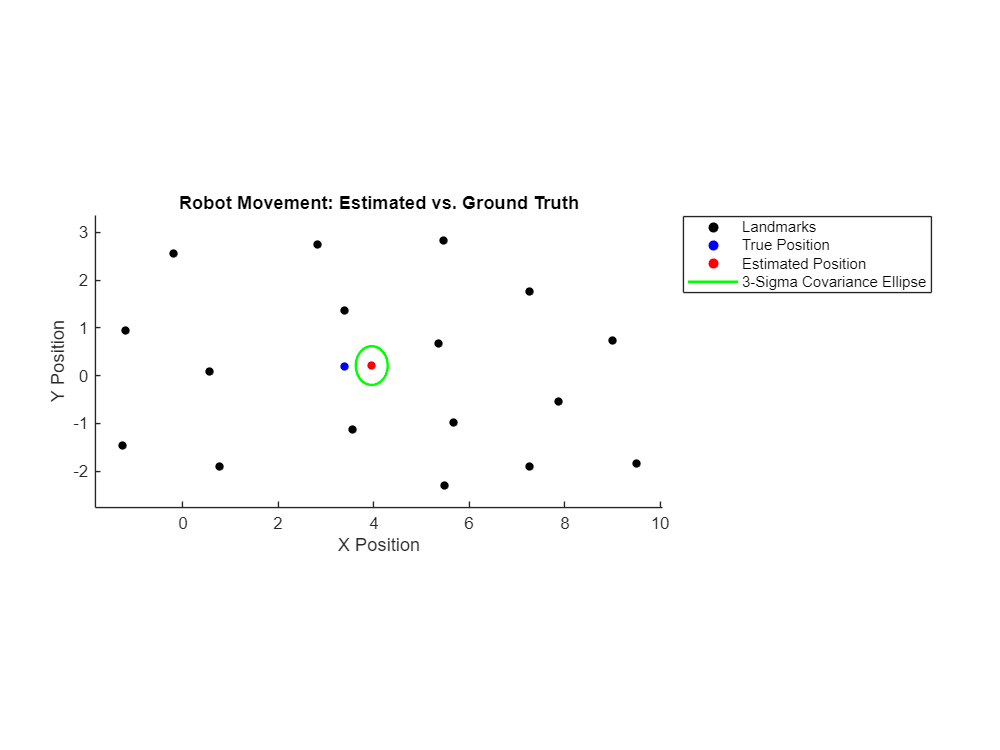

% Animation
[x_hat, y_hat, theta_hat, x_var, y_var, theta_var] = EKF( ...
    x_true,y_true,th_true, K, T, d, v, om, l, r, b, Q_k, R_k, h_func, ...
    H_x_func, H_w_func, g_func, G_x_func, 1, initial_states(:,:,1), ...
    initial_covs(:,:,1), false);

dot_size = 25;
pause_time = 0.0005;
sampling_factor = 13;

figure('Position', [100, 100, 800, 600]);
hold on;
axis equal;
xlim([min(x_true) - 1, max(x_true) + 1]);
ylim([min(y_true) - 1, max(y_true) + 1]);
title('Robot Movement: Estimated vs. Ground Truth');
xlabel('X Position');
ylabel('Y Position');

% Plot landmarks
scatter(l(:,1), l(:,2), dot_size, 'k', 'filled', 'DisplayName', 'Landmarks');

% Scatter plots for the current position
true_pos = scatter(x_true(1), y_true(1), dot_size, 'b', 'filled', ...
    'DisplayName', 'True Position');
est_pos = scatter(x_hat(1), y_hat(1), dot_size, 'r', 'filled', 'DisplayName', ...
    'Estimated Position');

% Initialize covariance ellipse
cov_ellipse = plot(0, 0, 'g', 'LineWidth', 1.5, 'DisplayName', ...
    '3-Sigma Covariance Ellipse');

legend('Location', 'northeastoutside');

% Animation loop
for k = 1:sampling_factor:K
    % Update positions
    true_pos.XData = x_true(k);
    true_pos.YData = y_true(k);
    est_pos.XData = x_hat(k);
    est_pos.YData = y_hat(k);

    % Update covariance ellipse parameters
    cov_matrix = [x_var(k) 0; 0 y_var(k)] * 9; 
    % 3-sigma is 9 times the variance
    theta = linspace(0, 2*pi, 100);
    % Transform circle to ellipse
    ellipse_points = sqrtm(cov_matrix) * [cos(theta); sin(theta)];
    cov_ellipse.XData = x_hat(k) + ellipse_points(1, :);
    cov_ellipse.YData = y_hat(k) + ellipse_points(2, :);

    % Refresh the plot
    drawnow;
    pause(pause_time);
end

% EKF IMPLEMENTATION
% CRLB is a boolean that dictates whether we evaluate the jacobians at the
% true state (true) or the previous estimated state (false)
function [x_hat, y_hat, theta_hat, x_var, y_var, theta_var] = EKF( ...
    x_true,y_true,th_true, K, T, d, v, om, l, r, b, Q_k, R_k, h_func, ...
    H_x_func, H_w_func, g_func, G_x_func, r_max, initial_state, initial_cov, ...
    CRLB)

    % Initializing EKF
    predicted_cov = zeros(3,3,K);
    predicted_state = zeros(3,1,K);
    estimated_cov = zeros(3,3,K);
    estimated_state = zeros(3,1,K);
    x_hat = zeros(K, 1);
    x_var = zeros(K, 1);
    y_hat = zeros(K, 1);
    y_var = zeros(K, 1);
    theta_hat = zeros(K, 1);
    theta_var = zeros(K, 1);
    
    % Initial condition
    estimated_cov(:,:,1) = initial_cov;
    estimated_state(:,:,1) = initial_state;
    predicted_cov(:,:,1) = estimated_cov(1);
    predicted_state(:,:,1) = estimated_state(1);
    
    x_hat(1) = estimated_state(1,1,1);
    y_hat(1) = estimated_state(2,1,1);
    theta_hat(1) = estimated_state(3,1,1);
    x_var(1) = estimated_cov(1,1,1);
    y_var(1) = estimated_cov(2,2,1);
    theta_var(1) = estimated_cov(3,3,1);
    
    % EKF
    for k = 2:K
        % Evaluate Jacobian and motion model at previous estimated state 
        % and current inputs with 0 noise
        x_prev = estimated_state(1,1,k-1);
        y_prev = estimated_state(2,1,k-1);
        theta_prev = estimated_state(3,1,k-1);
        % Predictor
        if CRLB
            H_x = H_x_func(T,normalize_angle(th_true(k-1)),v(k),0);
            H_w = H_w_func(T,normalize_angle(th_true(k-1)));
        else
            H_x = H_x_func(T,theta_prev,v(k),0);
            H_w = H_w_func(T,theta_prev);
        end
        Q = H_w * Q_k * H_w.'; 
        predicted_cov(:,:,k) = H_x * estimated_cov(:,:,k-1) * H_x.' + Q;
        predicted_state(:,:,k) = h_func(T, om(k), theta_prev, v(k), 0, 0, ...
            x_prev, y_prev);
        % normalize theta between -pi and pi
        predicted_state(3,1,k) = normalize_angle(predicted_state(3,1,k));
        % Building up y, G, and R based on visible landmarks
        x_curr = predicted_state(1,1,k);
        y_curr = predicted_state(2,1,k);
        theta_curr = predicted_state(3,1,k);
        L = 0;
        % Finding number of visible landmarks
        for i = 1:size(r, 2)
            % landmark seen
            if r(k,i) ~= 0 && r(k,i) < r_max
                L = L + 1;
            end
        end
        % Building y, y_pred, and G_x (State Jacobian)
        idx = 1;
        G_x = zeros(2*L, 3);
        y = zeros(2*L, 1);
        y_pred = zeros(2*L, 1);
        for i = 1:size(r, 2)
            % landmark seen
            if r(k,i) ~= 0 && r(k,i) < r_max
                % y
                y(2*idx-1) = r(k,i);
                % normalize phi between -pi and pi
                y(2*idx) = normalize_angle(b(k,i));
                % current landmark position
                x_l_curr = l(i,1);
                y_l_curr = l(i,2);
                % y_pred
                prediction = g_func(d,0,0,theta_curr,x_curr,x_l_curr,y_curr, ...
                    y_l_curr);
                y_pred(2*idx-1) = prediction(1);
                % normalize predicted phi between -pi and pi
                y_pred(2*idx) = normalize_angle(prediction(2));
                % State Jacobian
                if CRLB
                    G_x_l = G_x_func(d,normalize_angle(th_true(k)),x_true(k), ...
                        x_l_curr,y_true(k),y_l_curr);
                else
                    G_x_l = G_x_func(d,theta_curr,x_curr,x_l_curr,y_curr, ...
                        y_l_curr);
                end
                G_x(2*idx - 1, :) = G_x_l(1, :);
                G_x(2*idx,:) = G_x_l(2, :);
                % increment
                idx = idx + 1;
            end
        end
        % Building R (covariance matrix)
        R = zeros(2*L);
        for i = 1:L
            R(2*i-1, 2*i-1) = R_k(1,1);
            R(2*i, 2*i) = R_k(2,2);
        end
        % Kalman Gain
        K_gain = predicted_cov(:,:,k) * G_x.' / (G_x * predicted_cov(:,:,k) * ...
            G_x.' + R);
        % Corrector
        estimated_cov(:,:,k) = (eye(size(K_gain * G_x)) - K_gain * G_x) ...
            * predicted_cov(:,:,k);
        estimated_state(:,:,k) = predicted_state(:,:,k) + K_gain * (y - y_pred);
        % normalize estimated theta between -pi and pi
        estimated_state(3,1,k) = normalize_angle(estimated_state(3,1,k));
        % Partitioning findings into final arrays
        x_hat(k) = estimated_state(1,1,k);
        y_hat(k) = estimated_state(2,1,k);
        theta_hat(k) = estimated_state(3,1,k);
    
        estimation_var = diag(estimated_cov(:,:,k));
        x_var(k) = estimation_var(1);
        y_var(k) = estimation_var(2);
        theta_var(k) = estimation_var(3);
    end
end

% Used to ensure landmark and position bearings remain within the range -pi
% to pi
function theta = normalize_angle(in)
    theta = in;
    if theta > pi
        theta = theta - 2*pi;
    elseif theta < -pi
        theta = theta + 2*pi;
    end
end